Material tomado del módulo Mass-Spring-Damper Systems ubicado [aquí](https://es.mathworks.com/matlabcentral/fileexchange/94585-mass-spring-damper-systems)

# ¿Cómo se diseña un automóvil para asegurar un viaje suave?

Muchas partes de un vehículo contribuyen a garantizar un viaje cómodo para los pasajeros. El sistema de suspensión contiene componentes clave: neumáticos, amortiguadores y enlaces. Juntos, estos amortiguan la respuesta del vehículo a los baches y desniveles en la carretera.

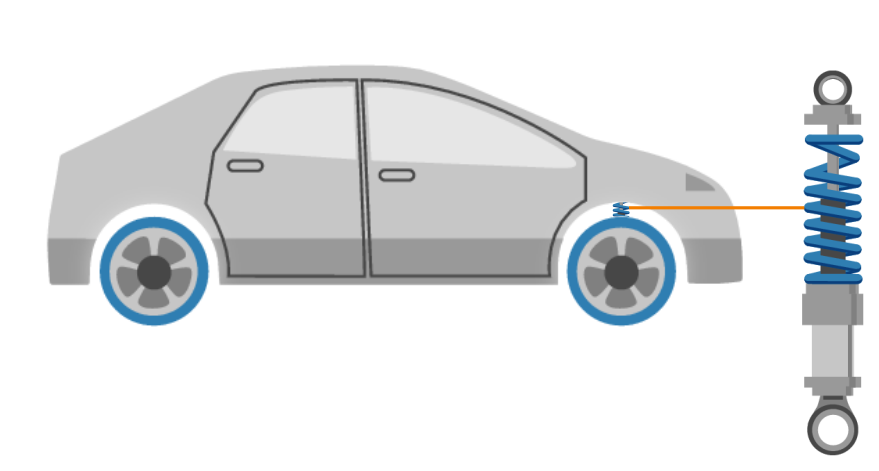

*Un amortiguador ayuda a proporcionar un viaje suave y reduce el desgaste de los componentes del vehículo.*

Los amortiguadores utilizan fluido hidráulico para disipar la energía mecánica, reduciendo la respuesta del vehículo ante un impacto. ¿Cómo se puede elegir la amortiguación adecuada para suavizar el viaje sin perder el control del vehículo? La respuesta está en el modelado dinámico. En este script interactivo, usted:

- examinará el modelo masa-resorte-amortiguador,

- resolverá sus soluciones en Simulink, y

- lo aplicará para ajustar la amortiguación de un sistema de suspensión para cumplir con los requisitos de diseño.

 **Consejo**: Si nunca ha usado Simulink antes, considere realizar el [curso Simulink Onramp](https://matlabacademy.mathworks.com/details/simulink-onramp/simulink): un curso introductorio gratuito de tres horas para Simulink

# El sistema masa-resorte-amortiguador

## 1. El modelo masa-resorte-amortiguador

El modelo masa-resorte-amortiguador es una idealización simple que puede aplicarse a una gran variedad de sistemas físicos vibratorios. Como su nombre indica, el sistema masa-resorte-amortiguador contiene tres componentes idealizados: una masa, un resorte y un amortiguador.

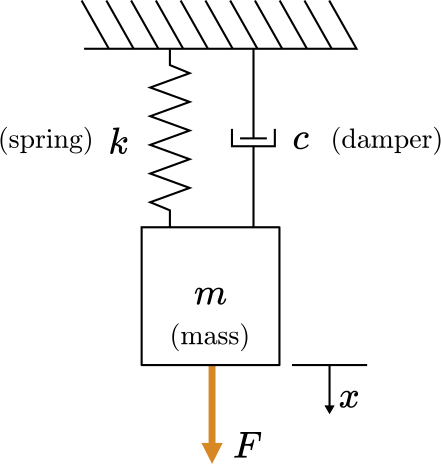

*Schematic of the mass-spring-damper system *

Varios parámetros determinan el comportamiento de este sistema mecánico:

- $k$: rigidez del resorte [N/m]

- $c$: coeficiente de amortiguamiento [N ⋅ s/m]

- $m$: masa [kg]

- $F$: fuerza aplicada externamente [N] (puede ser constante o dependiente del tiempo: F(t)

El comportamiento dependiente del tiempo del sistema se resuelve usando las variables:

- $t$: tiempo desde el inicio de la simulación [s]

- $x$: desplazamiento dependiente del tiempo ($x=x(t)$) de la masa desde la posición de equilibrio de referencia [m]

- $\dot{x}$: velocidad de la masa [m/s]

- $\ddot{x}$: aceleración de la masa [m/s$^2$]

Cuando se aplica una fuerza al sistema, la masa comenzará a vibrar. Con el tiempo, la vibración disminuye a medida que la energía mecánica se convierte en calor por el amortiguador.

 ** Intente**

- En papel, dibuje un diagrama de cuerpo libre de las fuerzas que actúan sobre la masa m*m*.

- Después de dibujar el diagrama de cuerpo libre, aplique la segunda ley de Newton para derivar la ecuación de movimiento:

                
$$m\ddot{x} \;=\;\;\sum Fuerzas
$$


showSolutionFBD = true; % Marque la casilla para ver la solución
if(showSolutionFBD)
    I = imread("mass_spring_damper_FBD.png");
    imshow(I);
end

#### Modelado de la suspensión del vehículo como un sistema masa-resorte-amortiguador

El sistema masa-resorte-amortiguador es adecuado para modelar un amortiguador, ya que los componentes del modelo corresponden directamente a los componentes mecánicos. El resorte y el amortiguador del modelo representan el resorte físico y el amortiguador, respectivamente. Estos dos componentes cumplen funciones complementarias para devolver suavemente el vehículo al equilibrio.

- El componente amortiguador disipa la energía mecánica, que se libera en forma de calor. Esto reduce el movimiento general del vehículo después de pasar por un bache.

- El resorte distribuye la respuesta al impacto a lo largo del tiempo. El impacto inicial comprime el resorte, seguido de oscilaciones regulares. Estas oscilaciones dan tiempo al amortiguador para disipar la energía mecánica.

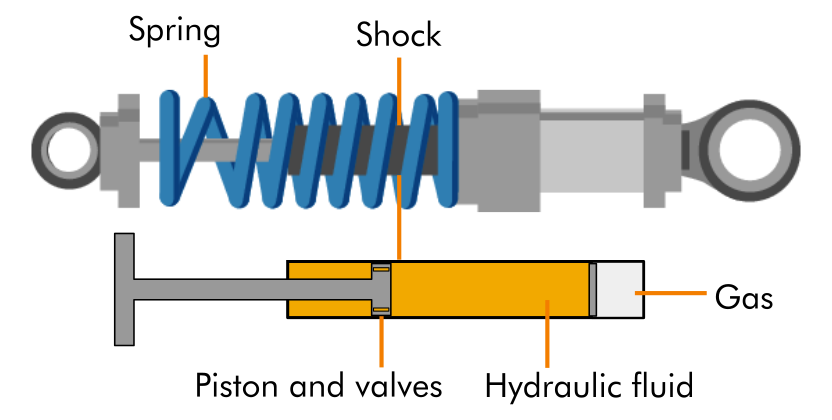

*Esquema simplificado de un sistema de amortiguador/resorte. Internamente, el amortiguador tiene un pistón que se mueve a través de un fluido hidráulico. La resistencia viscosa del fluido disipa la energía mecánica en forma de calor.*

En la idealización simple utilizada en este script, todo el sistema de suspensión del vehículo (en lugar de un solo amortiguador) se modela como un solo sistema masa-resorte-amortiguador con rigidez, $k$, y coeficiente de amortiguamiento, $c$. La masa, $m$, es la masa del propio vehículo. Si pasa por un bache, habrá aplicado una fuerza de impulso, $F$.

 Reflexione

- Intente dibujar un diagrama de cuerpo libre para un vehículo con una suspensión descrita por un solo sistema masa-resorte-amortiguador que ha pasado por una banda de frenado.

- ¿Qué características importantes quedan fuera del modelo al asumir un solo sistema masa-resorte-amortiguador para toda la suspensión?

## Manipulación de la ecuación masa-resorte-amortiguador usando operaciones simbólicas

La ecuación diferencial masa-resorte-amortiguador que usted derivó en la sección anterior es:

    $m\ddot{x} + c \dot{x} + kx =  F$.

Cuando se resuelve una ecuación diferencial ordinaria (EDO) en Simulink, es útil tenerla en la forma:  $\ddot{x} = \ldots$.Esta forma hace que la construcción del modelo de solución sea más sencilla. Solo se requieren dos pasos algebraicos simples para despejar $\ddot{x}$ aquí. Sin embargo, en sistemas de modelos más realistas, normalmente hay varias ecuaciones que deben resolverse simultáneamente, lo que hace que el álgebra sea tediosa y propensa a errores. Para prepararte para esos problemas, puedes utilizar cálculos simbólicos para despejar $\ddot{x}$ en la EDO masa-resorte-amortiguador.

 **Consejo**: Las variables y operaciones simbólicas de MATLAB no son iguales a las expresiones normales de MATLAB. Visita [esta página de documentación](https://www.mathworks.com/help/symbolic/create-symbolic-numbers-variables-and-expressions.html) para aprender un poco sobre la sintaxis básica de variables y expresiones simbólicas.

**Ejercicio:** En este ejercicio, definirás la ecuación en notación simbólica y luego despejarás$\ddot{x}$.

**Tarea 1**. Despeja $\ddot{x}$ en papel.

**Tarea 2. **Define siete variables simbólicas en el espacio proporcionado:x, x_dot, x_ddot, m, c, k, and F. Puedes definir múltiples variables simbólicas en MATLAB usando la siguiente sintaxis del comando:

syms x x_dot x_ddot m c k F
checkSyms() % Esto verifica si has definido las variables simbólicas

**Tarea 3. **Escribe la ecuación masa-resorte-amortiguador en términos de variables simbólicas y asígnala a msdEq.

  **Consejo**: El documento no proporciona explícitamente la traducción del texto solicitado, pero con base en mi conocimiento interno, aquí tienes la traducción al español:

Cuando escribes una ecuación simbólica, asignas toda la ecuación a una variable de MATLAB usando el signo igual. Esto significa que el signo igual en la ecuación simbólica debe escribirse como ==. Por ejemplo:

msdEq = m*x_ddot + c*x_dot + k*x  == F 
checkMSDeq(msdEq) % Esta función auxiliar (ubicada al final del script) verifica tu ecuación.

**Tarea 4. **Despeja `x_ddot `en la ecuación masa-resorte-amortiguador usando [`solve(equation, variable)`](https://www.mathworks.com/help/symbolic/solve.html) y asigna el resultado a `sltnMSD`. En esta sintaxis, `equation` es la ecuación simbólica que se va a resolver y `variable` es la variable simbólica respecto a la cual se va a despejar.

sltnMSD = solve(msdEq,x_ddot)
checkMSDSolve(sltnMSD) % Esta función auxiliar (ubicada al final del script) verifica tu ecuación.

 **Reflexión:**

- ¿La solución que encontraste en la Tarea 4 coincide con la que encontraste a mano en la Tarea 1?

## 3. Resolver una EDO de primer orden en Simulink

Para investigar la dinámica del sistema masa-resorte-amortiguador, puedes resolver sus soluciones en Simulink. Antes de resolver la EDO de segundo orden del sistema masa-resorte-amortiguador, puedes resolver una EDO de primer orden más simple. En Simulink, las EDOs se resuelven utilizando bloques integradores.

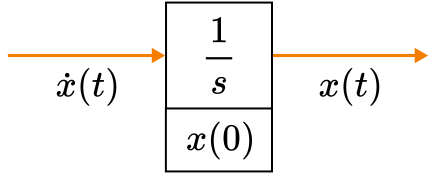

*Esquemático simplificado para resolver una EDO de primer orden en Simulink. El bloque integrador (etiquetado como *$1/s$*) integra una vez, reduciendo el orden de la derivada en uno. El bloque integrador también proporciona la condición inicial, *$x(0)$.

 **¿Sabías que?** El bloque integrador está etiquetado como$1/s$ porque la integración en el dominio del tiempo es equivalente a la división por $s$ en el dominio de Laplace.

** Ejercicio. **Considere la EDO:

    
$$\dot{x} = -x$$
 

sujeta a $x(0) = 10$

(a) Resuelve la solución analítica a mano. Escribe tu solución abajo en términos de $t$.

syms t;
xSltn = 10*exp(-t); % Use exp() para la exponencial
checkFirstOrder(xSltn)

(b) Crea un [nuevo modelo en Simulink](matlab: open_system(new_system('simpleODE'))) y construye el modelo de solución mostrado abajo realizando lo siguiente:

- Agrega un bloque integrador (**integrator**) y establece la condición inicial del bloque a $x(0) = 10$ (haz doble clic en el bloque para acceder al cuadro de diálogo).

- Agrega un bloque de ganancia (**gain**) con valor -1.

- Agrega un bloque de osciloscopio (**scope**).

- Conéctalos como se muestra.

- Ejecuta el modelo y haz doble clic en el osciloscopio para verificar que la salida coincide con la solución encontrada en (a). 

 **Consejo**: Haz doble clic en cualquier parte del lienzo de Simulink y escribe el nombre del bloque que deseas agregar.

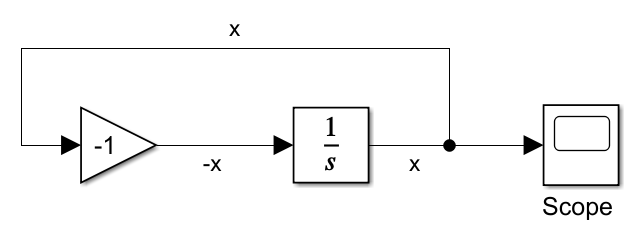

Simulink ODE solver for $\dot{x} = -x$.

 **Reflexión:**

- ¿Qué hace el bloque de ganancia ([gain block](https://www.mathworks.com/help/simulink/slref/gain.html))? 

- La entrada al integrador está etiquetada como $-x$.  ¿Por qué se utiliza $-x$ como entrada para el bloque integrador? 

- La salida del bloque integrador regresa a la entrada. ¿Por qué es esto necesario?

¿Tienes dificultades para crear tu modelo en Simulink? Consulta esta [publicación de blog](https://blogs.mathworks.com/simulink/2008/05/23/how-to-draw-odes-in-simulink/) para aprender más sobre cómo resolver EDOs en Simulink.

## 4. Resuelve el modelo masa-resorte-amortiguador en Simulink

En esta sección, resolverás la ecuación diferencial ordinaria (ODE) de segundo orden del sistema masa-resorte-amortiguador usando Simulink.

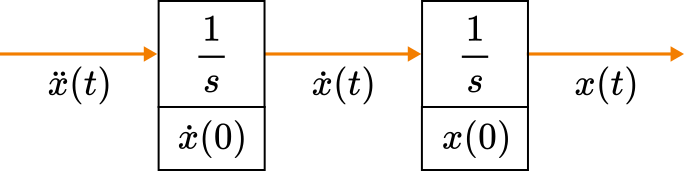

*Resolver una EDO de segundo orden en Simulink requiere dos bloques integradores.*

Para proporcionar la entrada al primer bloque integrador, puedes usar la expresión para $\ddot{x}$:

    $\ddot{x} = \frac{ F - c \dot{x} - kx}{m}$.

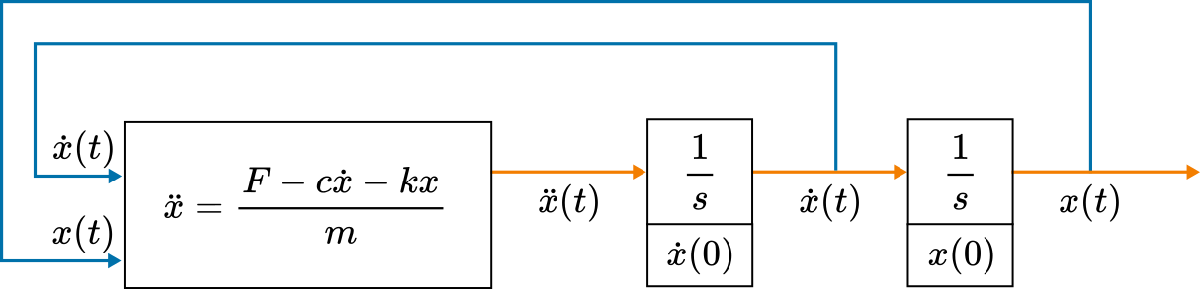

*Las entradas (*$\dot{x}$ y $x$) necesarias para calcular la expresión de $\ddot{x}$ se obtienen de las salidas de los bloques integradores.

Anteriormente, resolviste para en las ecuaciones de movimiento utilizando cálculos simbólicos en MATLAB. Puedes transferir esta expresión directamente a Simulink escribiéndola en un bloque **MATLAB Function**.

** Ejercicio. **Abre el modelo de Simulink [mfb.slx](matlab: open_system('mfb')) y completa el bloque MATLAB Function agregando la expresión de MATLAB para $\ddot{x}$.

yourExpression = char(sltnMSD) % Muestra tu expresión para x_ddot.
opensystem(mfd.slx)

- Puedes utilizar la expresión de MATLAB que calculaste simbólicamente arriba para `x_ddot `dentro del bloque MATLAB Function.

- Haz doble clic en el bloque MATLAB Function para editar el código MATLAB en su interior.

- Ejecuta el modelo para comprobar si tu expresión es correcta.

** Ejercicio. **En este ejercicio, completarás un modelo que resuelve la EDO de masa-resorte-amortiguador en Simulink.

Para calcular la solución de esta EDO de segundo orden, se requieren dos bloques de tipo Integrator.

- Abre [msd.slx](matlab: open_system('msd')).

- Agrega dos bloques de tipo **Integrator **para completar el sistema y conéctalos al sistema.

- Establece las condiciones iniciales de los bloques Integrator a $\dot{x}(0) = -3$ y $x(0)=2$

- Ejecuta el modelo y haz doble clic en el osciloscopio Scope para ver la salida. Si coincide con la solución mostrada a continuación, tu modelo es correcto.

            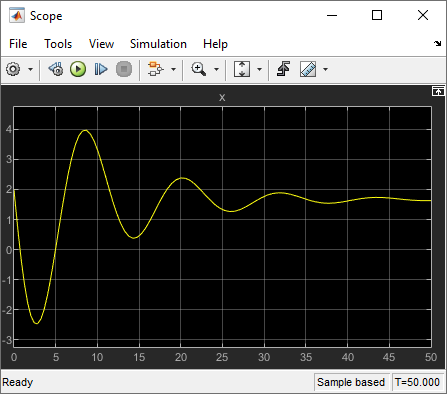

*            Solution del modelo masa-resorte-amortiguador*

¿Tienes problemas? Consulta el modelo completado: [msdSoln.slx](matlab: open_system('msdSoln')).

**Visualiza el movimiento del sistema masa-resorte-amortiguador**

Con el modelo completo, puedes visualizar el movimiento. El comando `sim` simula un modelo masa-resorte-amortiguador completado, [`msdSimulationOutput.slx`](matlab:open('.\msdSimulationOutput.slx')). La función local `animateMSD` crea una animación de la salida del modelo.

With the model complete, you can visualize the motion. The  `sim` command simulates a completed mass-spring-damper model, `msdSimulationOutput.slx`. The local function `animateMSD` creates an animation of the output from the model.

n = 50; % Número de pasos usados en la visualización

visualize = true; %  Haz clic en la casilla para mostrar la visualización
if(visualize)
    simOut = sim("msdSimulationOutput"); % Ejecuta el modelo de Simulink
    animateMSD(simOut.tout,simOut.yout,0.5,n)
end

 ** Intenta lo siguiente:**

Abre el modelo de [msdSimulationOutput.slx](matlab: open_system("msdSimulationOutput")) y luego prueba lo siguiente:

- Configura la amortiguación en 0. Después, vuelve a ejecutar esta sección del script. ¿Cómo se ve afectado el comportamiento?

- Disminuye la rigidez del resorte en el modelo y luego vuelve a ejecutar la animación aquí.

- Ajusta las condiciones iniciales en el modelo. Primero, cambia la posición inicial$x(0)$, luego cambia la velocidad inicial $\dot{x}(0)$. ¿Tienen estos cambios efectos diferentes o similares?

## 5. Ajusta la amortiguación de la suspensión utilizando el modelo masa-resorte-amortiguador

Ahora que has resuelto la EDO en Simulink, puedes aplicarla para ajustar la suspensión de un vehículo modelado como un sistema masa-resorte-amortiguador simple.

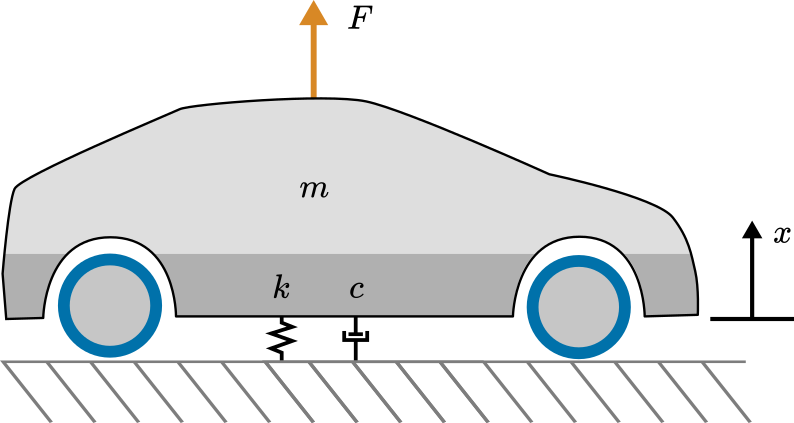

*Esquema del modelo masa-resorte-amortiguador aplicado a un vehículo*.* Toda la suspensión tiene una rigidez, *$k$, y un amortiguamiento, $c$. En reposo, la posición vertical del chasis del vehículo es $x=0$  

Tu objetivo en esta sección es ajustar la suspensión para que cumpla con los requisitos de diseño. 

** Ejercicio. **Considera un vehículo con las siguientes propiedades:

- Masa del vehículo: 1360 kg

- Rigidez de la suspensión: 26,000 N/m

Tu tarea es seleccionar un coeficiente de amortiguamiento, $c$, que cumpla con los siguientes requisitos de diseño. Después de encontrar un bache en la carretera, modelado como una fuerza de 9000 N aplicada durante 0.1 segundos, el vehículo debe:

- tener un desplazamiento vertical absoluto máximo de menos de 0.1 m después del impacto.

- después de 1 segundo, el desplazamiento vertical absoluto debe ser menor a 0.02 m, y

- el coeficiente de amortiguamiento debe ser lo más pequeño posible, siempre y cuando se cumplan los requisitos 1 y 2.

Supón que, inicialmente, el vehículo no tiene movimiento ni desplazamiento en la dirección vertical.

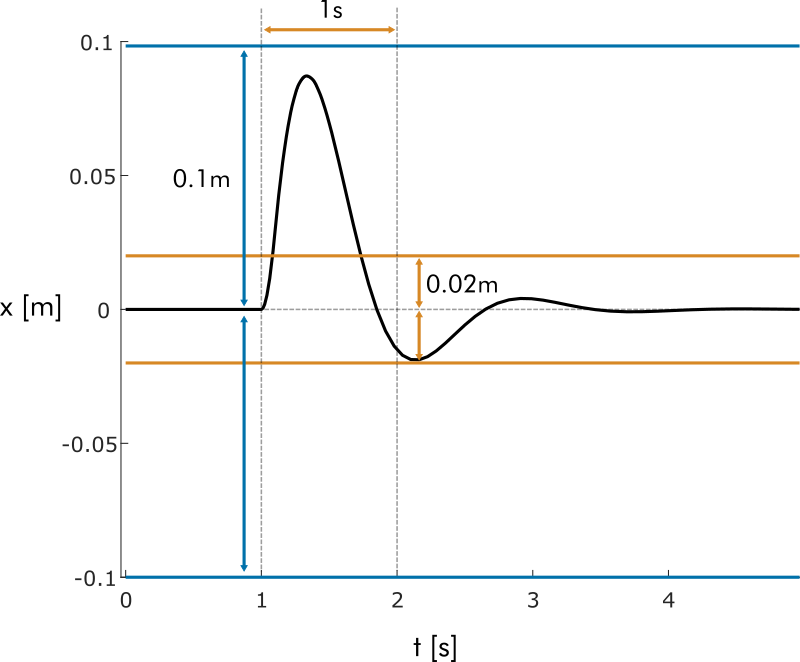

*Esquema de los requisitos de diseño. El desplazamiento vertical inicial debe ser menor a 0.1 m. Las oscilaciones subsiguientes deben tener una magnitud menor a 0.02 m.*

 ** Tareas. **Para ajustar el diseño y que cumpla con los requisitos, realiza lo siguiente:

- Abre el modelo [msdTune.slx](matlab: open_system('msdTune')). Este modelo tiene un subsistema enmascarado que contiene el modelo masa-resorte-amortiguador con el que trabajaste en la sección anterior. Puedes ver el interior de la máscara haciendo clic en la flecha ( ) para ver este modelo.

- Haz doble clic en la [máscara ](matlab: hilite_system('msdTune/mass-spring-damper model'); pause(1); hilite_system('msdTune/mass-spring-damper model','none');)del modelo y establece las condiciones iniciales de desplazamiento $x(0)$ y velocidad $\dot{x}(0)$.

- Establece los parámetros fijos del modelo: [*k*](matlab: hilite_system('msdTune/k'); pause(1); hilite_system('msdTune/k','none');) y [*m*](matlab: hilite_system('msdTune/m'); pause(1); hilite_system('msdTune/m','none');). El modelo ya aplica la fuerza de impulso correcta $F$, así que no modifiques el subsistema "F".

- Establece un coeficiente de amortiguamiento, [*c*](matlab: hilite_system('msdTune/c'); pause(1); hilite_system('msdTune/c','none');)*,* y ejecuta el modelo. Observa el comportamiento del rebote del vehículo en el [osciloscopio](matlab: hilite_system('msdTune/Scope'); pause(1); hilite_system('msdTune/Scope','none');).

- Ajusta el amortiguamiento hasta que se cumplan los tres requisitos.

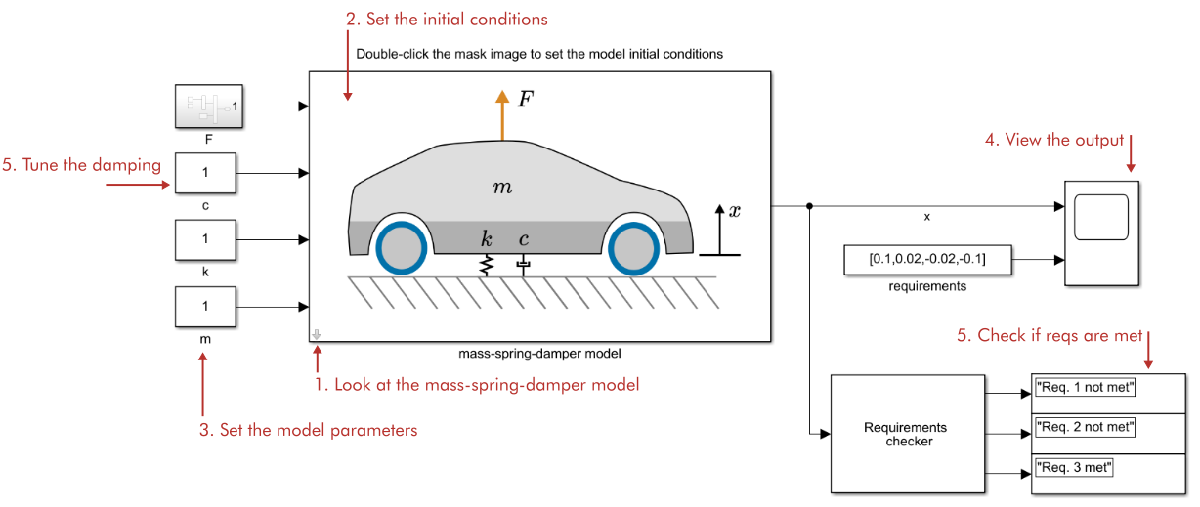

*Schematic of the Simulink model and where you should perform the tasks*

### 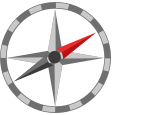Exploración adicional

En realidad, el sistema de suspensión de un vehículo es más complejo que un solo masa-resorte-amortiguador. Una mejora sencilla a este modelo utiliza dos masa-resorte-amortiguador: uno para la suspensión delantera y otro para la trasera. Para aprender más sobre este enfoque, puedes revisar la aplicación de [suspensión automotriz](https://www.mathworks.com/help/simulink/slref/automotive-suspension.html) en la documentación de Simulink.

**Funciones auxiliares**

Estas funciones verifican respuestas y generan animaciones.

function checkSyms
    varList = ["x","x_dot","x_ddot","m","c","k","F"];
    for k = 1:length(varList)
       varExists = evalin("caller",strcat("exist('",varList(k),"','var')"));
       if(varExists)
           varSym = evalin("caller",strcat("isequal(class(",varList(k),"),""sym"")"));
           if(varSym)
              disp(strcat("¡Éxito! ",varList(k)," es simbólica."))
           else
              warning(strcat(varList(k)," existe pero no es simbólica.")) 
           end
       else
         warning(strcat(varList(k)," no existe!"))
       end
    end
end

function correct = isEqualCheck(userSubmission,correctAnswer)
    correct = true;
    if( isequal(userSubmission,correctAnswer) )
        disp("Correcto!")
    else
        warning("Tu respuesta no coincide con el resultado esperado.")
        correct = false;
    end
end

function checkMSDeq(msdEqUser)
    syms x x_dot x_ddot m c k F
    msdEq = m*x_ddot + c*x_dot + k*x == F;
    isEqualCheck(solve(msdEqUser,x_ddot), solve(msdEq,x_ddot));
end

function checkMSDSolve(sltnUser)
    syms x x_dot x_ddot m c k F
    msdEq = m*x_ddot + c*x_dot + k*x == F;
    sltn = solve(msdEq,x_ddot);
    isEqualCheck(sltnUser,sltn);
    end

function checkFirstOrder(xSltnUser)
    syms t;
    xSltn = 10*exp(-t);
    correct = isEqualCheck(xSltnUser,xSltn);
    if(correct)
        tvec = linspace(0,10,500);
        figure("position",[1 1 400 200])
        plot(tvec,10*exp(-tvec))
        xlabel("$t$","Interpreter","latex")
        ylabel("$x(t)$","Interpreter","latex")
        title("Solution curve")
    end
end

function animateMSD(tin,xin,spacingMultiplier,steps)
    
    Nmass = size(xin,2); % Number of masses

    % Options that determine how the graph will look
    colors = lines(Nmass); 
    w = 1; % Mass width
    h = 2; % Height of masses
    y = 0; % Vertical position
    
    % Local variables
    t = linspace(tin(1),tin(end),steps);
    x = zeros(steps,Nmass);
    for k = 1:Nmass
        x(:,k) = interp1(tin,xin(:,k),t);
    end
    spacing = 2*max(abs(x),[],"all")*spacingMultiplier;
    xmax = spacing*2.5 + 2;
    
    % Loop to create the animation
    figure;    
    for j = 1:numel(t)
       
        subplot(2,1,1) % This shows the masses
        cla
        hold on
        x0k = 0;
        for k = 1:Nmass
            % Plot springs
            xc = spacing*k+x(j,k)-w/2;       
            xs = linspace(x0k,xc,12);
            ys = 0.25*(-1).^(1:numel(xs));
            plot(xs,ys + 0.5,SeriesIndex="none");
            % Plot dampers
            yd = 1.65;
            xd = x0k + (xc-x0k)*0.5+0.1;
            xd2 = x0k + (xc-x0k)*0.5;
            xd3 = x0k + (xc-x0k)*0.5 + 0.2;
            plot([x0k,xd,NaN,xd,xd],[yd,yd,NaN,yd-0.1,yd+0.1],SeriesIndex="none")
            plot([xd2,xd3,NaN,xd2,xd3,NaN,xd3,xd3,NaN,xd3,xc],[yd-0.15,yd-0.15,NaN,yd+0.15,yd+0.15,NaN,yd-0.15,yd+0.15,NaN,yd,yd],SeriesIndex="none")
            % Update position
            x0k = xc + w;
            % Plot masses
            x1 = spacing*k + x(j,k) - 0.5;
            rectangle("Position",[x1 y w h],"FaceColor",colors(k,:))
            text(x1 + w/2, h/2,"m_" + num2str(k),"HorizontalAlignment","center","color","w")
            % Plot x1, x2 distances
            quiver(spacing*k, y+h*1.1, x(j,k),0,"-","MaxHeadSize",1/(x(j,k))^2,SeriesIndex="none")
            plot([1;1]*[spacing*k, spacing*k+x(j,k)],[0.95;1.05]*(y*[1,1]+h*1.1),"-","markersize",12,SeriesIndex="none")
            text((spacing*k + spacing*k+x(j,k) )/2,(y+h*1.3),"x_"+num2str(k),"HorizontalAlignment","Center")
        end
        hold off
        axis([0,xmax,-1,3])
        set(gca,"ytick",[])
        xlabel("reference axis [m]")
    
        subplot(2,1,2) % This shows the position plots with moving markers
        cla
        hold on
        plot(t,x)
        for k = 1:Nmass
            plot(t(j),x(j,k),"o","MarkerFaceColor",colors(k,:),SeriesIndex="none")
        end 
        xlabel("t [s]")
        ylabel("x [m]")
        hold off
        box off
        drawnow
    end
end

% Suppress unused suggestions
%#ok<*UNRCH> 
